# set up

mass_4p = 9*10^-3;
distX = 0.047625;
disty = 0.047625;
r = sqrt(disty^2+distX^2);
moment_of_ineria = mass_4p/4*r^2;
m = .068;
J_xx = 0.69*10^-4;
J_yy = 0.775*10^-4;
J_zz = 1.5*10^-4;
slope_C_T = 0.01/3000

slope_C_T = 3.3333e-06

intercept_C_T = 0.08-slope_C_T*183.33

intercept_C_T = 0.0794

D1 = 6.6e-2

D1 = 0.0660

rho = 1.293;
Cp = 0.04;
g = 9.81;
J = [J_xx 0 0 ;
    0 J_yy 0;
    0 0 J_zz];
syms p q r p_dot q_dot r_dot
syms u v w u_dot v_dot w_dot
syms phi phi_dot theta theta_dot psi psi_dot
syms dT dA dE dR
syms PN PE PD PN_dot PE_dot PD_dot

## system from assigment 2


a = 1.948E-6;
b = 9.277E-8;
c = 9.277E-8;
d=1.017E-7;
kc = 0.22;
input = [dT;dA;dE;dR];
coeff = [1/a 1/b 1/c -1/d;
    1/a -1/b 1/c 1/d;
    1/a -1/b -1/c -1/d;
    1/a 1/b 0-1/c 1/d];
v_final1 = 1/4*coeff*input;
v_final = abs(v_final1);%Mixter
n1 = sqrt(v_final(1));
n2 = sqrt(v_final(2));
n3 = sqrt(v_final(3));
n4 = sqrt(v_final(4));
Jp=1.0207e-05;
hb = Jp*2*pi*(n1-n2+n3-n4);
Hb = [0;0;hb];
omega = [p;q;r];
Mb = cross(Hb,omega);%Momg
Momg1 = Mb(1);
Momg2 = Mb(2);
Momg3 = Mb(3);
v_b = [u;v;w];
K_c = [kc 0 0;
    0 kc 0;
    0 0 0];
F_b = -a*(n1^2+n2^2+n3^2+n4^2)*K_c*v_b;%Fa
fa1 = F_b(1);
fa2 = F_b(2);
fa3 = F_b(3);
Xt = 0;
Yt = 0;
Zt = -a*(n1^2+n2^2+n3^2+n4^2);%Ft
Mt1 = b*(n1^2-n2^2-n3^2+n4^2);
Mt2 = c*(n1^2+n2^2-n3^2-n4^2);
Mt3 = d*(-n1^2+n2^2-n3^2+n4^2);%Mt
Htheta = [1 0 -sin(theta);
    0 cos(phi) sin(phi)*cos(theta);
    0 -sin(phi) cos(phi)*cos(theta);];
omega = [p;q;r];
dotangle = inv(Htheta)*omega;%dotomege
phi_dot = dotangle(1);
theta_dot = dotangle(2);
psi_dot = dotangle(3);
cpsi = cos(psi);
spsi = sin(psi);
R_psi = [ cpsi spsi 0    ;...
          -spsi cpsi 0  ;...
          0 0 1  ];

cphi = cos(phi);
sphi = sin(phi);
R_phi = [ 1 0 0    ;...
          0 cphi sphi  ;...
          0 -sphi cphi  ];

ctheta = cos(theta);
stheta = sin(theta);
R_theta = [ ctheta 0 -stheta       ;....
            0 1  0 ;....
            stheta 0 ctheta ];
F_g_b = R_phi *  R_theta* R_psi;
fe = [0;0;-m*g];
fb = F_g_b*fe;%fg
fg1 = fb(1);
fg2 = fb(2);
fg3 = fb(3);
F_b = R_phi *  R_theta * R_psi;
v_e = inv(F_b)*v_b;%P
PN_dot = v_e(1);
PE_dot = v_e(2);
PD_dot = v_e(3);
F_t = [Xt;Yt;Zt];
F_a = [fa1;fa2;fa3];
F_g = [fg1;fg2;fg3];
M_t = [Mt1;Mt2;Mt3];
M_a = [0;0;0];
M_omg = [Momg1;Momg2;Momg3];
V_b = [u;v;w];
Omega = [p;q;r];
dotV = (1/m).*(F_t+F_a+F_g-cross(Omega,m.*V_b));
dotOmega = inv(J)*(M_t+M_a+M_omg-cross(Omega,J*Omega));
u_dot = dotV(1);
v_dot = dotV(2);
w_dot = dotV(3);
p_dot = dotOmega(1);
q_dot = dotOmega(2);
r_dot = dotOmega(3);


## 12th system


x_dot_1 = [PN_dot;
    PE_dot;
    PD_dot;
    w_dot;
    v_dot;
    phi_dot;
    p_dot;
    u_dot;
    theta_dot;
    q_dot;
    psi_dot;
    r_dot];
x_1 = [PN;
    PE;
    PD;
    w;
    v;
    phi;
    p;
    u;
    theta;
    q;
    psi;
    r];
u1 = [dT;
    dA;
    dE;
    dR ];
% didn't subs here
f_A = jacobian(x_dot_1,x_1); %A for 12th system
f_B = jacobian(x_dot_1,u1); % B for 12th system
y = x_1;

## initial conditions


R = R_phi *  R_theta * R_psi;
KC = 0.22;
func = @(x) - sin(x)/(cos(x)^2)-KC;
anss = fzero(func,0)

anss = -0.2119

f_hover = m*g*cos(anss)

f_hover = 0.6522

v_b = double(subs(R*[1;0;0],[phi theta psi],[0 anss 0]));
u0 = v_b(1);
v0 = v_b(2);
w0 = v_b(3);
p0 = 0;
q0 = 0;
r0 = 0;
phi_0 = 0;
theta_0 = anss;
psi_0 = 0;
phi_dot_0 = 0;
theta_dot_0 = 0;
psi_dot_0 = 0;
T_0 = f_hover;
A_0 = 0;
E_0 = 0;
R_0 = 0;
p_n0 = 0;
p_e0 = 0;
p_d0 = 0;
x_0 = [p_n0;p_e0;p_d0;w0;v0;phi_0;p0;u0;theta_0;q0;psi_0;r0];
u_0 = [T_0;A_0;E_0;R_0];
f_A1 = subs(f_A,[dT dA dE dR],[T_0 A_0 E_0 R_0]);
start_time = 0;
end_time =1.5;
start_step = 0.5;
end_step = 1.0;
dt = 0.005;
times = start_time:dt:end_time;
u_t = times.*[0;];
u_a = times.*[0;];
u_e = times.*[0;];
u_r = times.*[0;];
engage = start_step /dt;
disengage = end_step/dt;
u_t([engage:disengage]) = 0.01;
u_a([engage:disengage]) = 0.004;
u_e([engage:disengage]) = 0.004;
u_r([engage:disengage]) = 0.004;

## Throttle


x_dot_2 = [PD_dot;w_dot];
x_2 = [PD;w];
f_At = jacobian(x_dot_2,x_2);
f_At1 = double(subs(f_At,[phi theta psi],[phi_0 theta_0 psi_0]))

f_At1 =          0    0.9776
         0         0


f_Bt = jacobian(x_dot_2,dT);
f_Bt1 = double(subs(f_Bt,[dT dA dE dR],[T_0 A_0 E_0 R_0]))

f_Bt1 =          0
  -14.7059


throtsys = ss(f_At1,f_Bt1,eye(2),[0;0]);
tranferfunction_t = tf(throtsys)

tranferfunction_t =
 
  From input to output...
       -14.38
   1:  ------
        s^2
 
       -14.71
   2:  ------
         s
 
Continuous-time transfer function.



co_t =ctrb(f_At1,f_Bt1);
ob_t = obsv(f_At1,eye(2));
unco_t = length(f_At1)-rank(co_t)

unco_t = 0

unob_t = length(f_At1)-rank(ob_t)

unob_t = 0

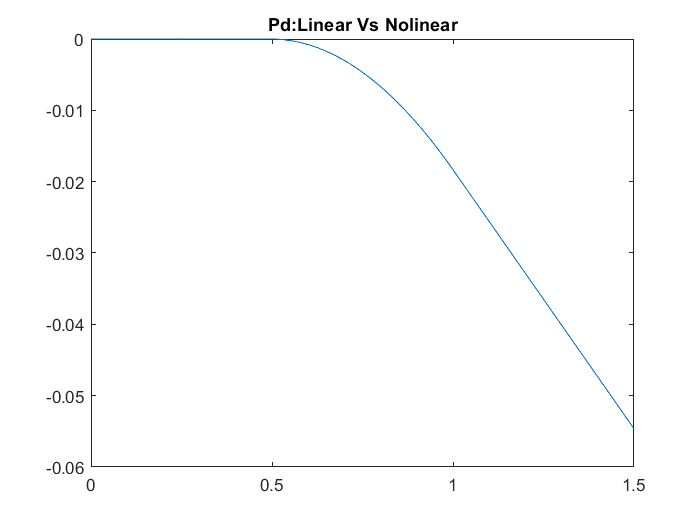

[~,time1,y_T] = lsim(throtsys,u_t,times);
figure ;
plot (time1,y_T(:,1))
hold on;
% plot (p_e.Time,p_e.Data(:,3))
title("Pd:Linear Vs Nolinear")
hold off;

## Aileron


x_dot_3 = [v_dot;
    phi_dot;
    p_dot];
x_3 = [v;
    phi;
    p];
f_AA = jacobian(x_dot_3,x_3);
f_AA1 = subs(f_AA,[phi theta psi],[phi_0 theta_0 psi_0]);
f_AA2 = subs(f_AA1,[dT dA dE dR],[T_0 A_0 E_0 R_0]);
f_AA3 = double(subs(f_AA2,[q w],[q0 w0]))

f_AA3 =    -2.1099   -9.5907   -0.2103
         0         0    1.0000
         0         0         0


f_BA = jacobian(x_dot_3,dA);
f_BA1 = double(subs(f_BA,[dT dA dE dR],[T_0 A_0 E_0 R_0]))

f_BA1 = 	1.0e+04 *

         0
         0
    1.4493


alisys = ss(f_AA3,f_BA1,eye(3),[0;0;0]);
tranferfunction_a = tf(alisys)

tranferfunction_a =
 
  From input to output...
       -3047 s - 1.39e05
   1:  -----------------
        s^3 + 2.11 s^2
 
       1.449e04
   2:  --------
         s^2
 
       1.449e04
   3:  --------
          s
 
Continuous-time transfer function.



co_a =ctrb(f_AA3,f_BA1);
ob_a = obsv(f_AA3,eye(3));

unco_a = length(f_AA3)-rank(co_a)

unco_a = 0

unob_a = length(f_AA3)-rank(ob_a)

unob_a = 0

[random,time2,y_A] = lsim(alisys,u_a,times);
plot (time2,y_A(:,2))
hold on;
% plot (angle.Time,angle.Data(:,1))
title("Phi:Linear Vs Nolinear")
legend("linear","nolinear")

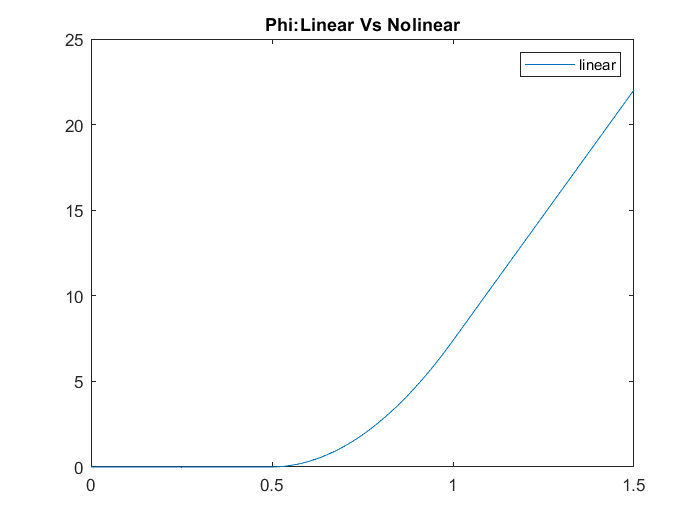

hold off;

## Elevator


x_dot_4 = [u_dot;
    theta_dot;
    q_dot];
x_4 = [u;
    theta;
    q];
f_AE = jacobian(x_dot_4,x_4);
f_AE1 = subs(f_AE,[phi theta psi],[phi_0 theta_0 psi_0]);
f_AE2 = subs(f_AE1,[dT dA dE dR],[T_0 A_0 E_0 R_0])

$$f\_AE2 = \left(\begin{array}{ccc} -\frac{819106040227184471164973205687637754128936853625}{388211372416021087647853783690262677096107081728} & \frac{981\,\cos\left(\frac{7632843621633271}{36028797018963968}\right)}{100} & -w\\ 0 & 0 & 1\\ 0 & 0 & 0 \end{array}\right)$$

F_AE3 = double(subs(f_AE2,[u p w],[u0 p0 w0]))

F_AE3 =    -2.1099    9.5907    0.2103
         0         0    1.0000
         0         0         0


f_BE = jacobian(x_dot_4,dE);
f_BE1 = double(subs(f_BE,[dT dA dE dR],[T_0 A_0 E_0 R_0]))

f_BE1 = 	1.0e+04 *

         0
         0
    1.2903


elsys = ss(F_AE3,f_BE1,eye(3),[0;0;0]);
tranferfunction_e = tf(elsys)

tranferfunction_e =
 
  From input to output...
       2713 s + 1.238e05
   1:  -----------------
        s^3 + 2.11 s^2
 
       1.29e04
   2:  -------
         s^2
 
       1.29e04
   3:  -------
          s
 
Continuous-time transfer function.



co_e =ctrb(F_AE3,f_BE1);
ob_e = obsv(F_AE3,eye(3));
unco_e = length(F_AE3)-rank(co_e)

unco_e = 0

unob_e = length(F_AE3)-rank(ob_e)

unob_e = 0

[~,time3,y_E] = lsim(elsys,u_e,times);
plot (time3,y_E(:,2))
hold on;
% plot (angle.Time,angle.Data(:,2))
title("Theta:Linear Vs Nolinear")
legend("linear","nolinear")

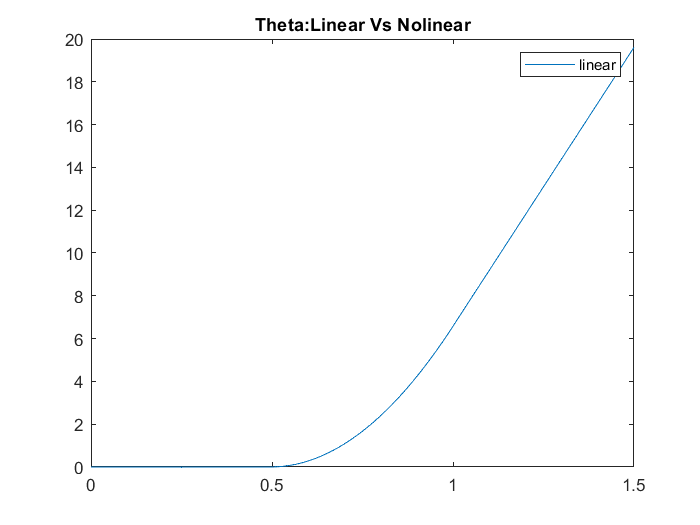

hold off;

## Rudder


x_dot_5 = [psi_dot;
    r_dot];
x_5 = [psi;
    r];
f_AR = jacobian(x_dot_5,x_5);
f_AR1 = subs(f_AR,[phi theta psi],[phi_0 theta_0 psi_0]);
f_AR2 = double(subs(f_AR1,[dT dA dE dR],[T_0 A_0 E_0 R_0]))

f_AR2 =          0    1.0229
         0         0


f_BR = jacobian(x_dot_5,dR);
f_BR1 = double(subs(f_BR,[dT dA dE dR],[T_0 A_0 E_0 R_0]))

f_BR1 = 	1.0e+03 *

         0
    6.6667


Rusys = ss(f_AR2,f_BR1,eye(2),[0;0]);
tranferfunction_r = tf(Rusys)

tranferfunction_r =
 
  From input to output...
       6819
   1:  ----
       s^2
 
       6667
   2:  ----
        s
 
Continuous-time transfer function.



co_r =ctrb(f_AR2,f_BR1);
ob_r = obsv(f_AR2,eye(2));
unco_r = length(f_AR2)-rank(co_r)

unco_r = 0

unob_r = length(f_AR2)-rank(ob_r)

unob_r = 0

[~,time4,y_R] = lsim(Rusys,u_r,times);
plot (time4,y_R(:,1))
hold on;
% plot (angle.Time,angle.Data(:,3))
title("Psi:Linear Vs Nolinear")
legend("linear","nolinear")

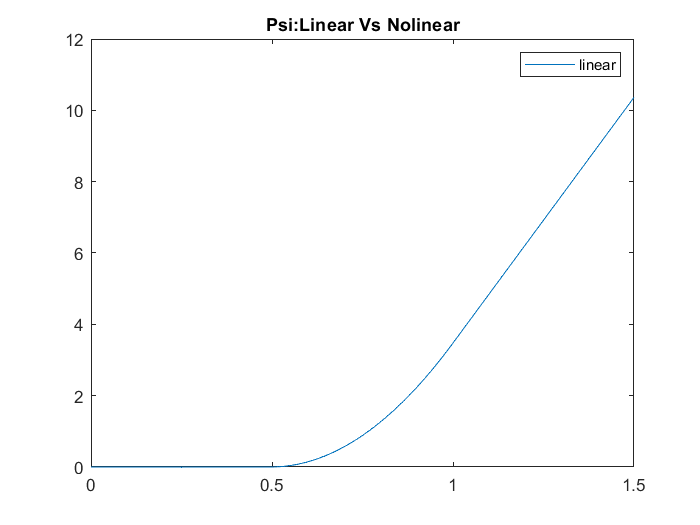

hold off;

## guid


x_dot_6 = [PN_dot;
    PE_dot];
x_6 = [PN;
    PD];
u_5 = [u;psi];
u_g = times.*u_5;
u_final = double(subs(u_g,[dT dA dE dR phi theta psi u w v],[T_0 A_0 E_0 R_0 phi_0 theta_0 psi_0 u0 w0 v0]))

u_final =          0    0.0049    0.0098    0.0147    0.0196    0.0244    0.0293    0.0342    0.0391    0.0440    0.0489    0.0538    0.0587    0.0635    0.0684    0.0733    0.0782    0.0831    0.0880    0.0929    0.0978    0.1027    0.1075    0.1124    0.1173    0.1222    0.1271    0.1320    0.1369    0.1418    0.1466    0.1515    0.1564    0.1613    0.1662    0.1711    0.1760    0.1809    0.1858    0.1906    0.1955    0.2004    0.2053    0.2102    0.2151    0.2200    0.2249    0.2297    0.2346    0.2395
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

timedou = [times;times]

timedou =          0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1550    0.1600    0.1650    0.1700    0.1750    0.1800    0.1850    0.1900    0.1950    0.2000    0.2050    0.2100    0.2150    0.2200    0.2250    0.2300    0.2350    0.2400    0.2450
         0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1550    0.1600    0.1650    0.1700    0.1750    0.1800    0.1850    0.1900    0.1950    0.2000    0.2050    0.2100    0.2150    0.2200    0.2250    0.2300    0.2350    0.240

f_Ag = jacobian(x_dot_6,x_6);
f_Ag1 = subs(f_Ag,[phi theta psi],[phi_0 theta_0 psi_0]);
f_Ag2 = double(subs(f_Ag1,[dT dA dE dR],[T_0 A_0 E_0 R_0]))

f_Ag2 =      0     0
     0     0


f_Bg = jacobian(x_dot_6,u_5);
f_Bg1 = subs(f_Bg,[dT dA dE dR],[T_0 A_0 E_0 R_0]);
f_Bg2 = subs(f_Bg1,[phi theta psi],[phi_0 theta_0 psi_0]);
f_Bg3 = double(subs(f_Bg2,[u w v],[u0 w0 v0]))

f_Bg3 =     0.9776         0
         0    1.0000


glsys = ss(f_Ag2,f_Bg3,eye(2),[0 0;0 0]);
tranferfunction_g = tf(glsys)

tranferfunction_g =
 
  From input 1 to output...
       0.9776
   1:  ------
         s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       1
   2:  -
       s
 
Continuous-time transfer function.



co_g =ctrb(f_Ag2,f_Bg3);
ob_g = obsv(f_Ag2,eye(2));
unco_r = length(f_Ag2)-rank(co_g)

unco_r = 0

unob_r = length(f_Ag2)-rank(ob_g)

unob_r = 0

%[~,time4,y_R] = lsim(glsys,u_final,timedou);
plot (time4,y_R(:,1))
hold on;
% plot (p_e.Time,p_e.Data(:,1))
title("PE:Linear Vs Nolinear")
legend("linear","nolinear")

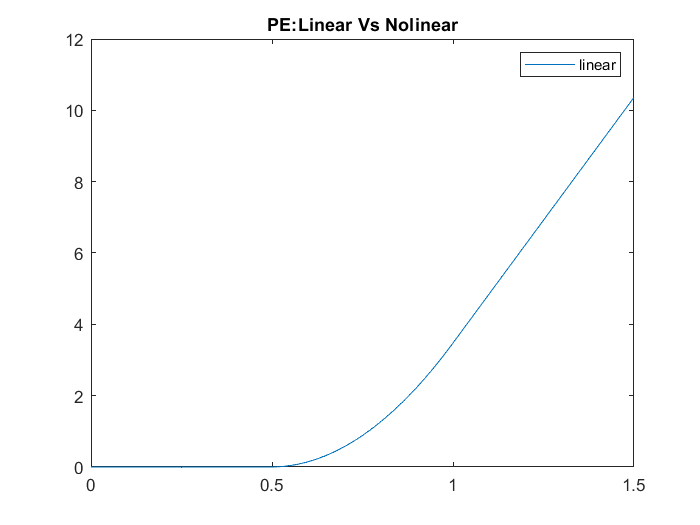

hold off;